## Log Data1

predicted_apogee_times1 = prediction_times;
predicted_apogees1 = predicted_apogee_altitudes;
predicted_apogee_sigmas1 = predicted_apogee_sigmas;



## Log Data2

predicted_apogee_times2 = prediction_times;
predicted_apogees2 = predicted_apogee_altitudes;
predicted_apogee_sigmas2 = predicted_apogee_sigmas;

## Plotting

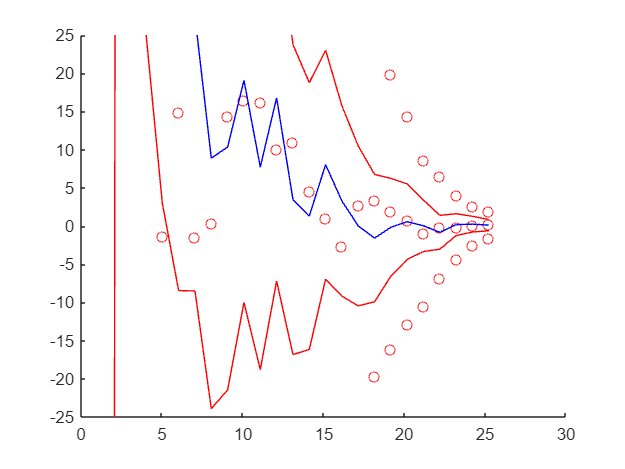

clf;
%Plot the first set of data, set up to be the particle filter data
hold on;
ylim([-25,25]);
scatter(predicted_apogee_times1, predicted_apogees1 - apogee_altitude, 'r'); 
scatter(predicted_apogee_times1, predicted_apogees1 + predicted_apogee_sigmas1 * 3 - apogee_altitude, 'r');
scatter(predicted_apogee_times1, predicted_apogees1 + predicted_apogee_sigmas1 * -3 - apogee_altitude, 'r'); 

%Plot the second set of data, set up to be the UKF data
plot(predicted_apogee_times2, predicted_apogees2 - apogee_altitude, 'b'); 
plot(predicted_apogee_times2, predicted_apogees2 + predicted_apogee_sigmas2 * 3 - apogee_altitude, 'r');
plot(predicted_apogee_times2, predicted_apogees2 + predicted_apogee_sigmas2 * -3 - apogee_altitude, 'r'); 
hold off;